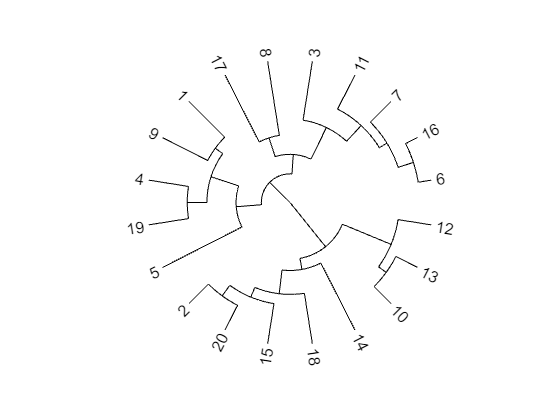

author : slandarer


% ringTreeDemo

% 20个变量
figure(1)
rng('default')
X=rand(20,3);
ringTree(X);

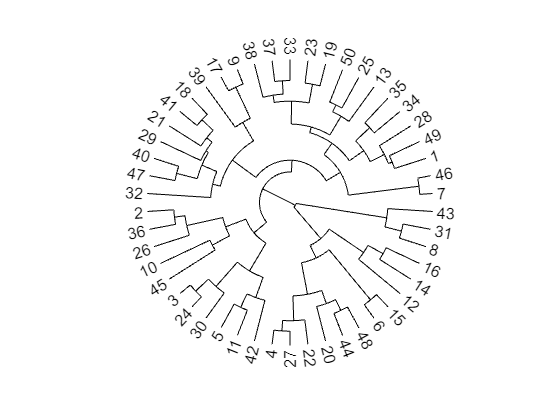

author : slandarer



% 50个变量
figure(2)
X=rand(50,3);
ringTree(X);

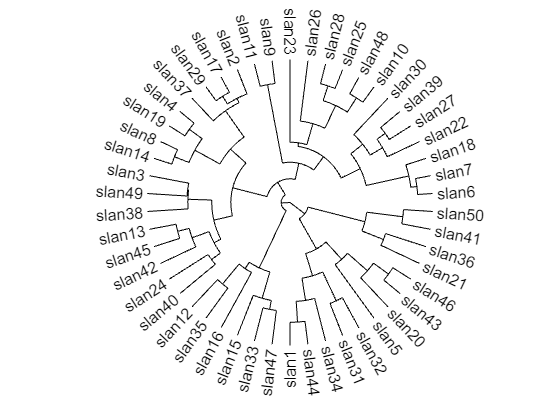

author : slandarer



% 随便定义变量名
Name{50}=[];
for i=1:50
    Name{i}=['slan',num2str(i)];
end
figure(3)
X=rand(50,3);
ringTree(X,Name);



% 修饰文字和树
figure(4)
X=rand(50,3);
[treeHdl,txtHdl]=ringTree(X);

author : slandarer


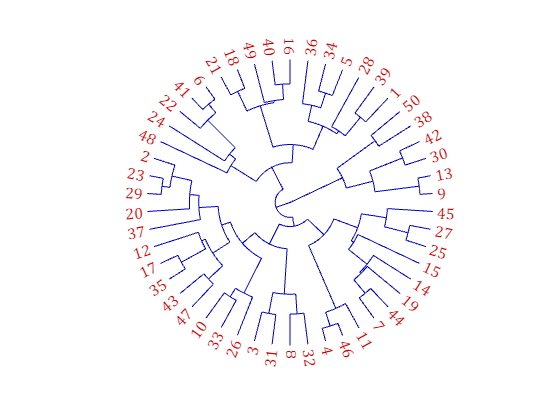

for i=1:length(treeHdl)
    treeHdl(i).Color=[0,0,.8];
end
for i=1:length(txtHdl)
    txtHdl(i).FontName='Cambria';
    txtHdl(i).Color=[.8,0,0];
end

function [treeHdl,txtHdl]=ringTree(Data,Name)
% @author : slandarer
fig=gcf;
fig.Color=[1,1,1];
ax=gca;hold on
ax.XLim=[-1.2,1.2];
ax.YLim=[-1.2,1.2];
ax.DataAspectRatio=[1,1,1];
ax.XColor='none';
ax.YColor='none';
ax.Tag='author : slandarer';
disp(ax.Tag);

fig1=figure();
tree1=linkage(Data,'average');
[~,~,order1]=dendrogram(tree1,0,'Orientation','top');

theta1=0;
theta2=pi*2;
theta3=(theta2-theta1)./size(Data,1);
theta4=theta1+theta3/2;
theta5=theta2-theta3/2;

LineSet1=fig1.Children.Children;
maxY1=0;
for i=1:length(LineSet1)
    maxY1=max(max(LineSet1(i).YData),maxY1);
end
tS=linspace(0,1,50);
for i=1:length(LineSet1)
    tX=LineSet1(i).XData;
    tY=LineSet1(i).YData;
    tR=(maxY1-tY)./maxY1;
    tT=theta4+(theta5-theta4).*(tX-1)./(size(Data,1)-1);
    tR=[tR(1),tR(2).*ones(1,50),tR(4)];
    tT=[tT(1),tT(2)+tS.*(tT(3)-tT(2)),tT(4)];
    treeHdl(i)=plot(ax,tR.*cos(tT),tR.*sin(tT),'Color','k','LineWidth',.7);
end
close(fig1)

if nargin<2
    for i=1:size(Data,1)
        Name{i}=num2str(i);
    end
end
for i=1:length(order1)
    tT=theta4+(theta5-theta4).*(i-1)./(size(Data,1)-1);
    if tT<pi/2||tT>3*pi/2
        txtHdl(i)=text(ax,(1/30+1).*cos(tT),(1/30+1).*sin(tT),Name{order1(i)},...
        'FontSize',12,'Rotation',tT./pi.*180);
    else
        txtHdl(i)=text(ax,(1/30+1).*cos(tT),(1/30+1).*sin(tT),Name{order1(i)},...
        'FontSize',12,'Rotation',tT./pi.*180+180,'HorizontalAlignment','right');
    end
end
end